# Quy hoạch động thích nghi với đối tượng xe lò xo

Mô hình đối tượng như sau:

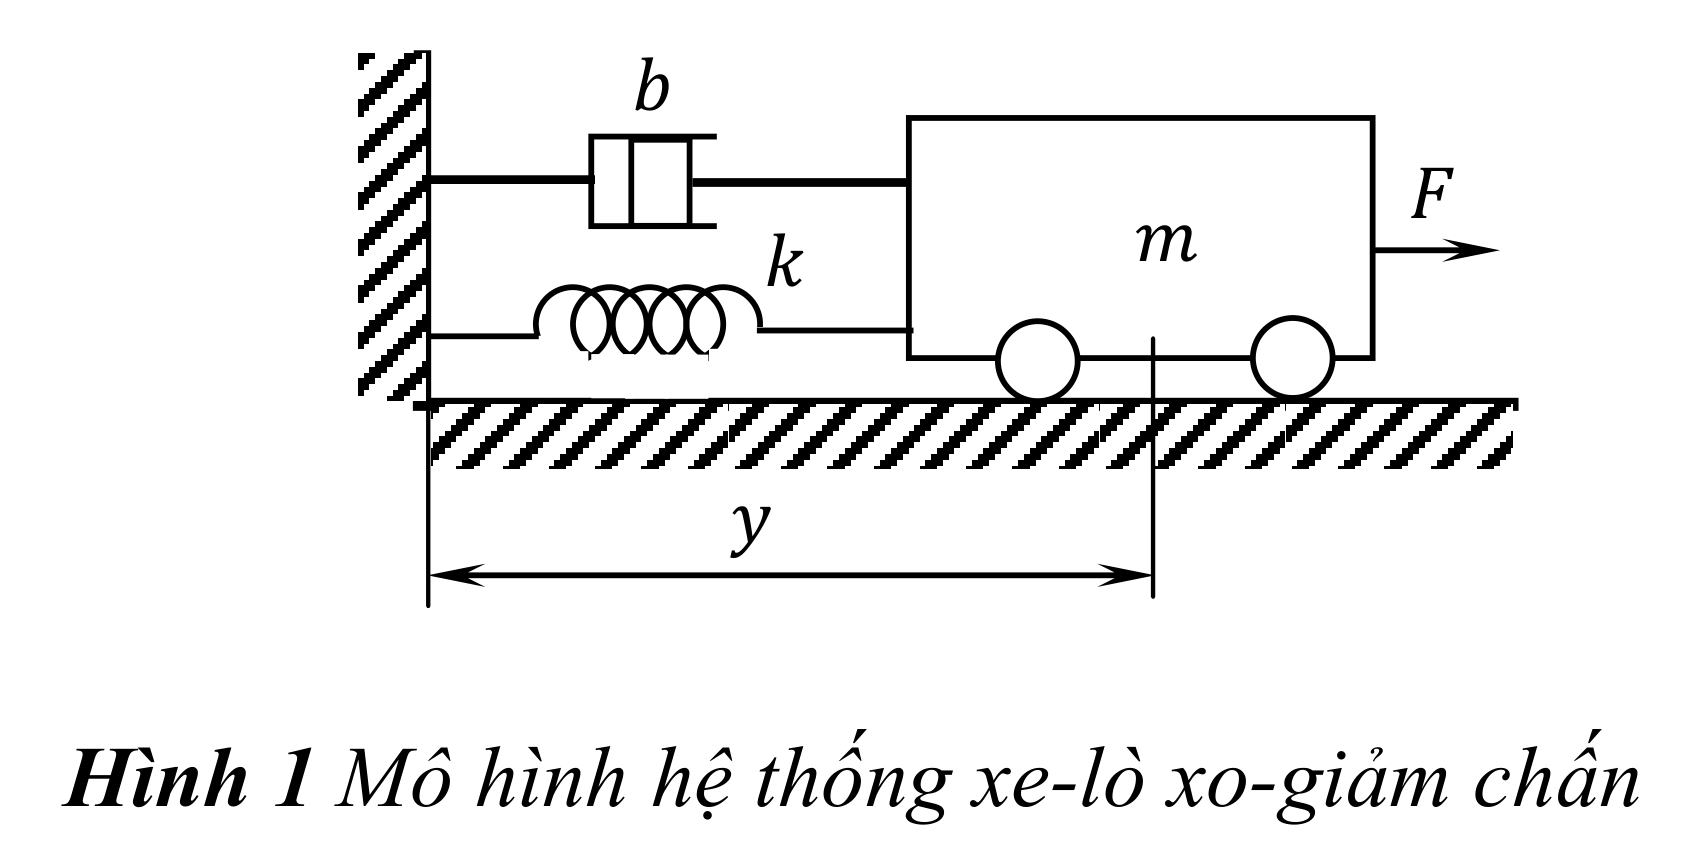

Phương trình động học liên tục của hệ thống được miêu tả như sau:


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{1}{m}k & -\frac{1}{m}b
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}
\end{array}\right\rbrack \cdot u$$



$$y=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


Từ đó suy ra được các ma trận sau của hệ liên tục:

## Bước 1: Tìm phương trình hệ số hệ thống và giải tìm nghiệm LQR cơ bản

### Bước 1.1: Tìm phương trình hệ số hệ thống

(Bước 1: chạy khởi tạo các tham số của hệ thống)

clear
clc
% Các tham số của hệ thống
k = 0.05 %Nm

k = 0.0500

b = 0.1 %N/(m/s)

b = 0.1000

m = 1 %kg

m = 1

T_sample = 0.01 % giây

T_sample = 0.0100


% Khởi tạo ma trận trạng thái của đối tượng
A_c = [0        1;
       -k/m     -b/m];
B_c = [0;
       1/m];
C_c = [1 0];
D_c = 0;

% Từ đó quy đổi về phương trình rời rạc của đối tượng với T_sample cho
% trước
sys_cont_represent = ss(A_c, B_c, C_c, D_c);
sys_disc_represent = c2d(sys_cont_represent, T_sample, 'zoh');
disp('Kết quả ma trận rời rạc của hệ');

Kết quả ma trận rời rạc của hệ


A_d = sys_disc_represent.A

A_d =     1.0000    0.0100
   -0.0005    0.9990


B_d = sys_disc_represent.B

B_d =     0.0000
    0.0100


C_d = sys_disc_represent.C

C_d =      1     0


D_d = sys_disc_represent.D

D_d = 0

Sau đó cần phải trích xuất kích thước ngõ vào, ngõ ra và kích thước biến trạng thái của hệ thống dựa trên các ma trận `A, B, C, D`. 

Trong đó:

- Số lượng biến trạng thái của hệ: `n `phụ thuộc vào kích thước của ma trận vuông A.

- Số lượng ngõ vào (input size) phu thuộc vào kích thước thứ 2 của ma trận B.

- Số lượng ngõ ra (output size) phụ thuộc vào kích thước thứ 1 của ma trận C.

disp('Kích thước biến trạng thái: ')

Kích thước biến trạng thái: 


states_size = size(A_d, 1)

states_size = 2


disp('Kích thước ngõ vào: ')

Kích thước ngõ vào: 


inputs_size = size(B_d, 2)

inputs_size = 1


disp('Kích thước ngõ ra: ')

Kích thước ngõ ra: 


outputs_size = size(C_d, 1)

outputs_size = 1

### Bước 1.2: Tìm lời giải giải tích cho phương pháp dlqr

Từ đó có thể quyết định được kích thước của ma trận $\mathbf{Q,R}
$.

Trong đó: $\mathbf{Q}\in {\mathbf{R}}^{\mathrm{n}\cdot \mathrm{n}}$ và $\mathbf{R}\in {\mathbf{R}}^{\mathrm{m}}$

(Vế trái là ma trận ký hiệu, vế phải biểu diễn tập ma trận số thực kích thước tương ứng)

Q = eye(states_size);
R = eye(outputs_size);

Sau đó gắn hệ số ta cần tối ưu cho ma trận Q này. Ở trường hợp này, ta cần tối ưu vị trí đến sớm nhất có thể nên ta đặt hệ số tối ưu cho biến trạng thái vị trí lớn:

Q(1,1) = 2;

Tới đây hoàn toàn có thể giải được luật điều khiển:

[S,K_LQR] = dlqr(A_d,B_d,Q,R)

S =     1.3522    1.8231


K_LQR =   274.1767  136.5112
  136.5112  183.9002


## Bước 2: Luật điều khiển quy hoạch động thích nghi

% Khởi tạo theta
A = A_d

A =     1.0000    0.0100
   -0.0005    0.9990


B = B_d

B =     0.0000
    0.0100


C = C_d

C =      1     0


D = D_d

D = 0

x=[10;2.2];
theta_size = 6;
theta = rand(theta_size,1); % Theta là vector cột
H22 = theta(theta_size);
H21 = [theta(3); theta(5)];
K=inv(H22)*H21';
t=0;
gama=1;
N=10;
xx=K';
for k=1:N
P = eye(theta_size,theta_size);
Z=[];
Y=[];
for i=1:30
explore=rand;
xold=x;
sim('hethong_RR1.mdl');
phi_1 = [xold(1)^2; xold(1)*xold(2); xold(1)*u; xold(2)^2; xold(2)*u; u^2];
r=[xold(1);xold(2)]'*Q*[xold(1);xold(2)]+u*R*u;
u=-K*x;
phi_2=[x(1)^2;x(1)*x(2);x(1)*u;x(2)^2;x(2)*u;u^2];
phi=phi_1-phi_2;
Z=[Z; phi']; 
Y=[Y; r];
end
theta=(Z'*Z)\Z'*Y;
H22=theta(theta_size);
H_21 = [theta(3); theta(5)];
K=H22\(H21');
end
K

K =     0.0594    0.5544


[S,K_LQR]=dlqr(A,B,Q,R)

S =     1.3522    1.8231


K_LQR =   274.1767  136.5112
  136.5112  183.9002
